# One Charged Plate and a Point Particle

% The variables
syms a d v r real positive;
assume(d>0)
assume(r>=0)
assume(v>=0)
assumeAlso (v < 1)
assume(a>=0)
taylorOrder = 13;

vp = [v,0,0];

## The vectors

d= distance from the charge to the plate

r=radius of a circle in the plate

The speed of light is 1 (c=1)

R = (d^2+r^2)^(1/2) % total distance from a point in the plate to the charge

$$R = \sqrt{r^{2}+d^{2}}$$


% Get two points per circle. 
vec_l1 = [d,r*cos(a),r*sin(a)]/R  % velocity vector of light from a point 1 in left positive plate 

$$vec\_l1 = \left(\begin{array}{ccc} \frac{d}{\sqrt{r^{2}+d^{2}}} & \frac{r\,\cos\left(a\right)}{\sqrt{r^{2}+d^{2}}} & \frac{r\,\sin\left(a\right)}{\sqrt{r^{2}+d^{2}}} \end{array}\right)$$

vec_l2 = [d,-r*cos(a),-r*sin(a)]/R  % velocity vector of light from a point 2 in left positive plate 

$$vec\_l2 = \left(\begin{array}{ccc} \frac{d}{\sqrt{r^{2}+d^{2}}} & -\frac{r\,\cos\left(a\right)}{\sqrt{r^{2}+d^{2}}} & -\frac{r\,\sin\left(a\right)}{\sqrt{r^{2}+d^{2}}} \end{array}\right)$$

r_vec_l1 = (vec_l1 - vp) % left plate relative velocity of particle (v in light speed fraction =v/c)

$$r\_vec\_l1 = \left(\begin{array}{ccc} \frac{d}{\sqrt{r^{2}+d^{2}}}-v & \frac{r\,\cos\left(a\right)}{\sqrt{r^{2}+d^{2}}} & \frac{r\,\sin\left(a\right)}{\sqrt{r^{2}+d^{2}}} \end{array}\right)$$

r_vec_l2 = (vec_l2 - vp) % left plate relative velocity of particle (v in light speed fraction =v/c)

$$r\_vec\_l2 = \left(\begin{array}{ccc} \frac{d}{\sqrt{r^{2}+d^{2}}}-v & -\frac{r\,\cos\left(a\right)}{\sqrt{r^{2}+d^{2}}} & -\frac{r\,\sin\left(a\right)}{\sqrt{r^{2}+d^{2}}} \end{array}\right)$$

## The Cosine Square


dprd_l1 = simplify(simplifyFraction(dot(vec_l1,r_vec_l1)^2/dot(r_vec_l1,r_vec_l1))) % Cosine^2 left plate

$$dprd\_l1 = \frac{d^{2}+r^{2}+d^{2}\,v^{2}-2\,d\,v\,\sqrt{r^{2}+d^{2}}}{r^{2}\,v^{2}+d^{2}+r^{2}+d^{2}\,v^{2}-2\,d\,v\,\sqrt{r^{2}+d^{2}}}$$

dprd_l2 = simplify(simplifyFraction(dot(vec_l2,r_vec_l2)^2/dot(r_vec_l2,r_vec_l2))) % Cosine^2 left plate

$$dprd\_l2 = \frac{d^{2}+r^{2}+d^{2}\,v^{2}-2\,d\,v\,\sqrt{r^{2}+d^{2}}}{r^{2}\,v^{2}+d^{2}+r^{2}+d^{2}\,v^{2}-2\,d\,v\,\sqrt{r^{2}+d^{2}}}$$

## The Net Force of the Two Points


dforce = ((dprd_l1/R^2)*vec_l1 + (dprd_l2/R^2)*vec_l1); % net Force in the x direction first points.
dforce = simplify(expand(dforce),'Steps',100); % Two charges
dforce_x = dforce(1)

$$dforce\_x = \begin{array}{l} \frac{2\,d\,r^{4}+d^{5}\,\left(2+2\,v^{2}\right)+2\,d^{3}\,r^{2}\,\left(2+v^{2}\right)-4\,d^{2}\,v\,\sigma_{1}}{{\left(r^{2}+d^{2}\right)}^{2}\,\left(\sigma_{1}+v^{2}\,\sigma_{1}-2\,d^{3}\,v-2\,d\,r^{2}\,v\right)}\\ \mathrm{where}\\ \sigma_{1}={\left(r^{2}+d^{2}\right)}^{3/2} \end{array}$$

## Check at v = 0, r =0

df_v_zero = simplify(subs(dforce,[v,r],[0,0]),'Steps',100) % Due to the two point charges

$$df\_v\_zero = \left(\begin{array}{ccc} \frac{2}{d^{2}} & 0 & 0 \end{array}\right)$$

df_v_one = simplify(subs(dforce,[v,r],[v,0]),'Steps',100) % Due to the two point charges

$$df\_v\_one = \left(\begin{array}{ccc} \frac{2}{d^{2}} & 0 & 0 \end{array}\right)$$

## Integrate all the angles

dforce_xT = expand(taylor(dforce_x,v,Order=taylorOrder));
%dforce_xT = dforce_x;

dcircle = int(dforce_xT,a,0,pi); % From zero to pi i.e., the full circle

dcircle = simplify(dcircle,steps=100); % Net force of the two full circles with charge density
df_v_zero = simplify(subs(dcircle,[v,r],[v,0]),'Steps',100) % Net force of the full zero radius circle (point)

$$df\_v\_zero = \frac{2\,\pi }{d^{2}}$$

## Integrate for all values of r


dtotf = simplify(expand(r*dcircle),steps=100)/pi; % Add all the circles
%dtotf = expand(taylor(dtotf,v,Order=taylorOrder));
totf = int(dtotf,r,0,r);
totf = simplify(totf); % The force on a charge due a charge surface density


## Set the Plates Radius to Infinity


totfInf = simplify(limit(totf,r,Inf)) % Net force by plate charge density

$$totfInf = 2-\frac{4\,v^{2}}{3}-v^{3}+\frac{4\,v^{4}}{15}+\frac{2\,v^{5}}{3}+\frac{4\,v^{6}}{105}-\frac{v^{7}}{3}+\frac{4\,v^{8}}{315}+\frac{4\,v^{9}}{15}+\frac{4\,v^{10}}{693}-\frac{v^{11}}{5}+\frac{4\,v^{12}}{1287}$$

totfInfV0 = subs(totfInf,v=0)

$$totfInfV0 = 2$$


totfInfRel = simplify(totfInf/totfInfV0)

$$totfInfRel = 1-\frac{2\,v^{2}}{3}-\frac{v^{3}}{2}+\frac{2\,v^{4}}{15}+\frac{v^{5}}{3}+\frac{2\,v^{6}}{105}-\frac{v^{7}}{6}+\frac{2\,v^{8}}{315}+\frac{2\,v^{9}}{15}+\frac{2\,v^{10}}{693}-\frac{v^{11}}{10}+\frac{2\,v^{12}}{1287}$$

## Plots

figure(1)
plotrange = [0,0.99];
fplot(totfInfRel,plotrange)
hold on
relEq = sqrt(1-v^2)

$$relEq = \sqrt{1-v^{2}}$$

relEqApx = taylor(relEq,v,Order=taylorOrder)

$$relEqApx = 1-\frac{v^{2}}{2}-\frac{v^{4}}{8}-\frac{v^{6}}{16}-\frac{5\,v^{8}}{128}-\frac{7\,v^{10}}{256}-\frac{21\,v^{12}}{1024}$$

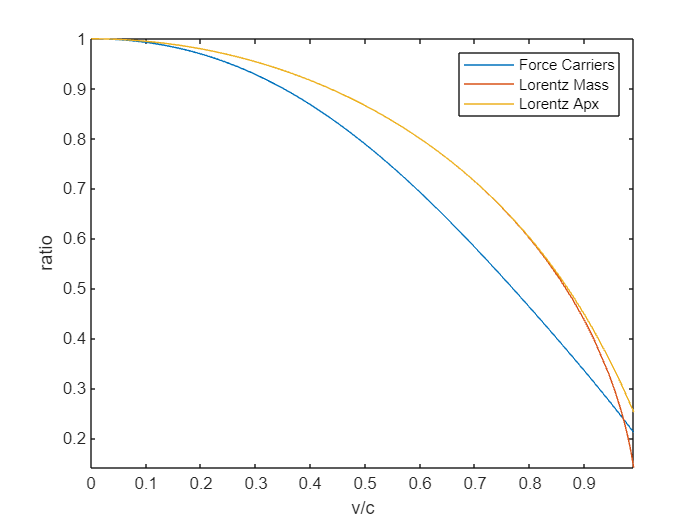

fplot(relEq,plotrange)
fplot(relEqApx,plotrange)
xlabel('v/c') 
ylabel('ratio') 
legend({'Force Carriers',"Lorentz Mass","Lorentz Apx"},'Location','northeast')
hold off